## 图形和矩阵

### 示例一——bucky

图形是一组相互之间具有指定连接或边的节点。图形有许多形状和大小。Buckminster Fuller 多面穹顶（也就是足球或碳 60 分子的形状）的连接图就是这样一个示例。

在 MATLAB® 中，可以使用 `bucky` 函数来生成多面穹顶的图形。

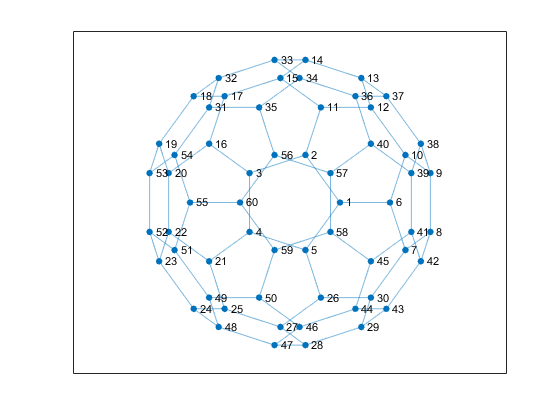

figure
[B,V] = bucky;
G = graph(B);
p = plot(G);
axis equal
p.XData = V(:,1);
p.YData = V(:,2);

`bucky` 函数可用于创建图形，因为它返回邻接矩阵。邻接矩阵是一种表示图形中的节点和边的方式。

要构造图形的邻接矩阵，节点应按 1 至 N 进行编号。如果节点 i 连接至节点 j，则 N×N 矩阵的每个元素 (i,j) 都设置为 1，否则设置为 0。因此，对于无向图，邻接矩阵是对称的，但有向图不必如此。

### 示例二——图示邻接矩阵

简单的图形及其关联的邻接矩阵

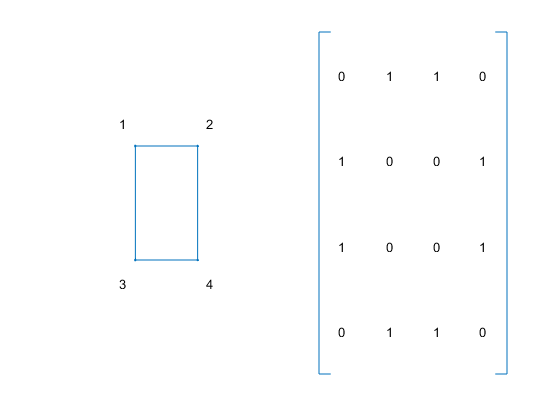

% Define a matrix A.
A = [0 1 1 0 ; 1 0 0 1 ; 1 0 0 1 ; 0 1 1 0];

% Draw a picture showing the connected nodes.
figure
subplot(1,2,1);
gplot(A,[0 1;1 1;0 0;1 0],'.-');
text([-0.2, 1.2 -0.2, 1.2],[1.2, 1.2, -.2, -.2],('1234')', ...
   'HorizontalAlignment','center')
axis([-1 2 -1 2],'off')

% Draw a picture showing the adjacency matrix.
subplot(1,2,2);
xtemp = repmat(1:4,1,4);
ytemp = reshape(repmat(1:4,4,1),16,1)';
text(xtemp-.5,ytemp-.5,char('0'+A(:)),'HorizontalAlignment','center');
line([.25 0 0 .25 NaN 3.75 4 4 3.75],[0 0 4 4 NaN 0 0 4 4])
axis off tight

### 稀疏矩阵

稀疏矩阵特别有助于表示非常大的图形。这是因为每个节点通常只会连接到少数几个其他节点。因此，对于大型图形，邻接矩阵中非零项的密度通常比较小。布基球邻接矩阵就是一个很好的示例，因为它是一个 60×60 的对称稀疏矩阵，仅包含 180 个非零元素。此矩阵的密度仅为 5%。

由于邻接矩阵定义图形，因此您可以使用邻接矩阵中的条目子集来绘制布基球的一部分。

### `adjacency`

使用 `adjacency` 函数为图形创建新的邻接矩阵。通过对该邻接矩阵进行索引创建一个新的较小图形，以显示布基球的一个半球中的节点。

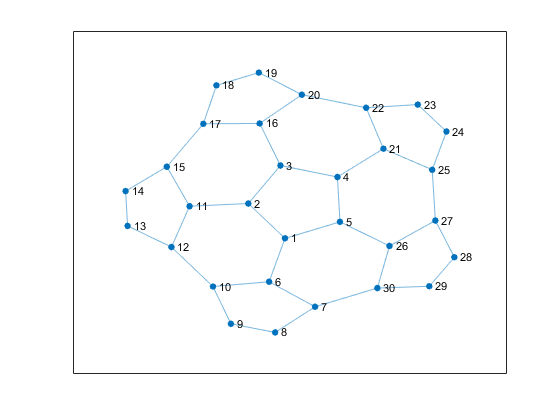

figure
A = adjacency(G);
H = graph(A(1:30,1:30));
h = plot(H);

### `spy`

要实现此半球的邻接矩阵可视化，请使用 `spy` 函数对邻接矩阵中的非零元素的轮廓进行绘图。

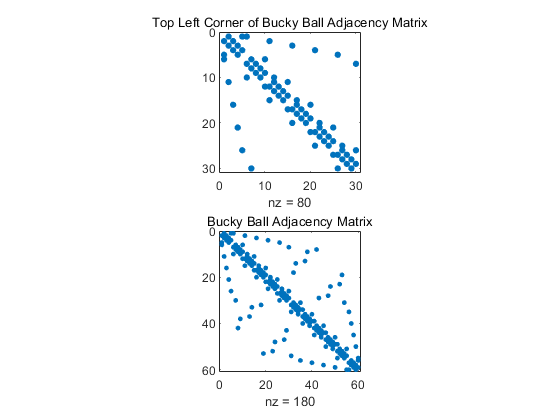

figure
subplot(211)
spy(A(1:30,1:30))
title('Top Left Corner of Bucky Ball Adjacency Matrix')
subplot(212)
spy(A)
title('Bucky Ball Adjacency Matrix')

## 修改现有图的节点和边

### **添加节点**

s = [1 1 1 2];
t = [2 3 4 3];
G = graph(s,t)

G =   graph - 属性:

    Edges: [4×1 table]
    Nodes: [4×0 table]


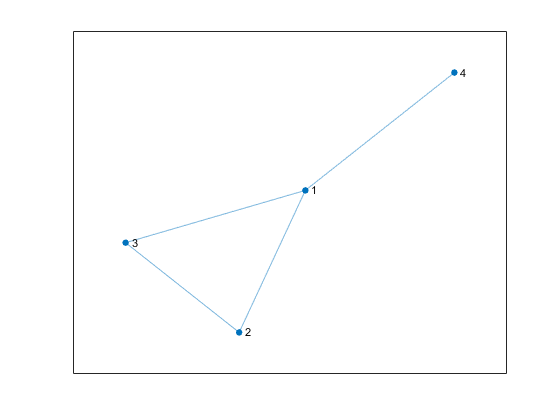

figure
plot(G)

G.Edges

ans = 4×1 table
    EndNodes
    ________

     1    2 
     1    3 
     1    4 
     2    3 


## 添加图节点名称、边权重和其他属性

### 创建图

s = [1 1 2 2 3];
t = [2 4 3 4 4];
G = digraph(s,t)

G =   digraph - 属性:

    Edges: [5×1 table]
    Nodes: [4×0 table]


figure
subplot(221)
plot(G)
% 添加节点名称
G.Nodes.Name = {'First' 'Second' 'Third' 'Fourth'}';
subplot(222)
plot(G)
% 添加路径权重
G.Edges.Weight = [10 20 30 40 50]';
G.Edges

ans = 5×2 table
          EndNodes          Weight
    ____________________    ______

    'First'     'Second'      10  
    'First'     'Fourth'      20  
    'Second'    'Third'       30  
    'Second'    'Fourth'      40  
    'Third'     'Fourth'      50  


G.Nodes.Size = [10 20 10 30]';
% 使用索引查看部分权重
G.Edges([1 3],:)

ans = 2×2 table
          EndNodes          Weight
    ____________________    ______

    'First'     'Second'      10  
    'Second'    'Third'       30  


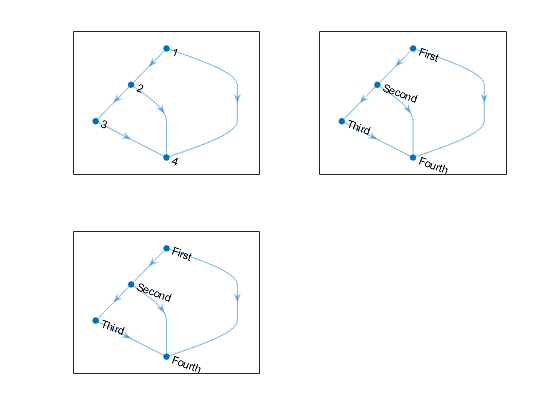

subplot(223)
plot(G)

% 添加自定义属性，可以将任何变量添加到 G.Nodes 和 G.Edges 中，来定义图节点或边的属性。
G.Edges.Power = {'on' 'on' 'on' 'off' 'off'}';
G.Edges

ans = 5×3 table
          EndNodes          Weight    Power
    ____________________    ______    _____

    'First'     'Second'      10      'on' 
    'First'     'Fourth'      20      'on' 
    'Second'    'Third'       30      'on' 
    'Second'    'Fourth'      40      'off'
    'Third'     'Fourth'      50      'off'


### **为图论图的节点和边添加标签**

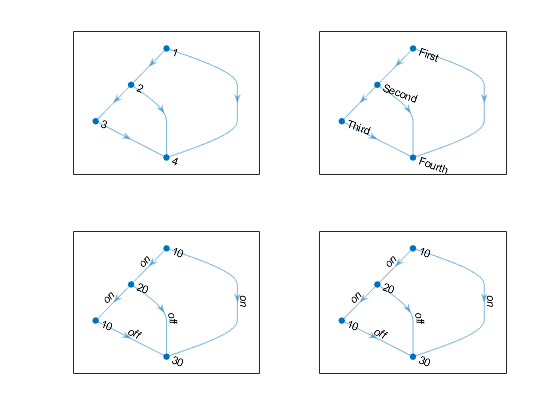

p =   GraphPlot - 属性:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'10'  '20'  '10'  '30'}
     EdgeLabel: {'on'  'on'  'on'  'off'  'off'}
         XData: [2 1.5000 1 2]
         YData: [4 3 2 1]
         ZData: [0 0 0 0]

  显示 所有属性


subplot(224)
p = plot(G,'EdgeLabel',G.Edges.Power,'NodeLabel',G.Nodes.Size)

## 图的绘制和自定义

使用 `plot` 函数绘制 `graph` 和 `digraph` 对象。默认情况下，`plot` 会检查图的大小和类型，以确定要使用的布局。生成的图窗窗口不包含轴刻度线。但是，如果使用 `XData`、`YData` 或 `ZData` 名称-值对组指定节点的 *(x,y)* 坐标，图窗将包含轴刻度线。

节点数不超过 100 的图会自动包含节点标签。节点标签使用节点名称（如果可用）；否则标签为数值节点索引。

G = graph(bucky);
figure('name','graph-1')
p = plot(G)

p =   GraphPlot - 属性:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×60 cell}
     EdgeLabel: {}
         XData: [1×60 double]
         YData: [1×60 double]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]

  显示 所有属性


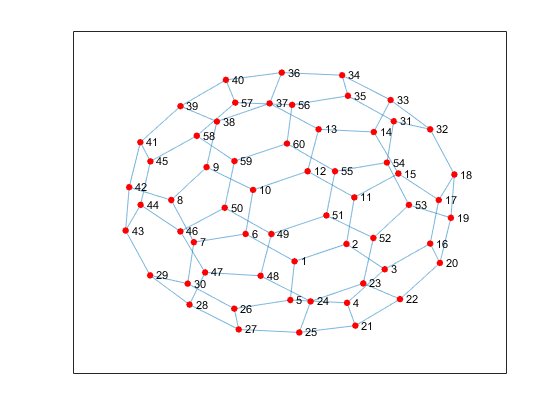

p.NodeColor = 'red';

### **更改图节点的布局**

n = 12;
A = delsq(numgrid('L',n));
G = graph(A,'omitselfloops')

G =   graph - 属性:

    Edges: [130×2 table]
    Nodes: [75×0 table]


figure('name','graph-2')
subplot(221)
p = plot(G)

p =   GraphPlot - 属性:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×75 cell}
     EdgeLabel: {}
         XData: [1×75 double]
         YData: [1×75 double]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]

  显示 所有属性


layout(p,'force3')
view(3)

### **按比例对节点着色**

根据图节点的出入度为它们着色。在该图中，所有内部节点都具有最大度数 4，沿图边的节点的度数为 3，角节点具有最小度数 2。将该节点着色数据存储为 `G.Nodes` 中的变量 `NodeColors`。

subplot(222)
p = plot(G)

p =   GraphPlot - 属性:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×75 cell}
     EdgeLabel: {}
         XData: [1×75 double]
         YData: [1×75 double]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]

  显示 所有属性


layout(p,'force3')
view(3)
G.Nodes.NodeColors = degree(G);
p.NodeCData = G.Nodes.NodeColors;
colorbar

### **按权重列出的边线宽度**

subplot(223)
p = plot(G)

p =   GraphPlot - 属性:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {1×75 cell}
     EdgeLabel: {}
         XData: [1×75 double]
         YData: [1×75 double]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]

  显示 所有属性


layout(p,'force3')
view(3)
G.Edges.Weight = randi([10 250],130,1);
G.Edges.LWidths = 7*G.Edges.Weight/max(G.Edges.Weight);
p.LineWidth = G.Edges.LWidths;

### **提取子图**

subplot(224)
H = subgraph(G,[1:31 36:41])

H =   graph - 属性:

    Edges: [61×3 table]
    Nodes: [37×1 table]


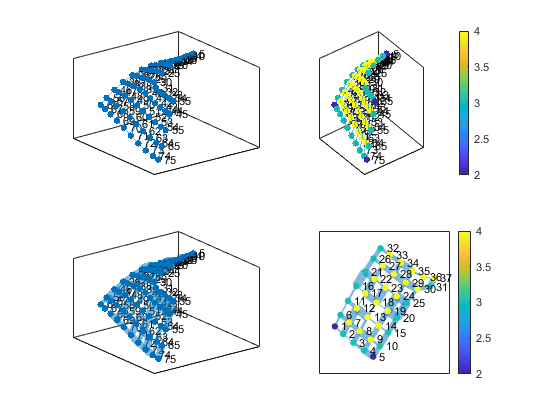

p1 = plot(H,'NodeCData',H.Nodes.NodeColors,'LineWidth',H.Edges.LWidths);
colorbar